filenameCRS = "C:\Users\dfpsi\sciebo\ProjektSeminar\dataset\subject1\stage1\imgB1.mat";
load(filenameCRS);

filenameVRS = "C:\Users\dfpsi\sciebo\ProjektSeminar\dataset\subject1\stage1\imgV2.mat";
load(filenameVRS);

% Organize the data into "snapshots": spatial is rows, time is columns
stdMap = std(imgV2,[],3);
imgV2(stdMap < max(stdMap(:)) * 0.25) = 0;
flatV = reshape(imgV2(:,:,1000:1500),32*32,[]);
X1 = flatV(:,1:end-1);
X2 = flatV(:,2:end);


% Rank reduction
r = 20;
[U,S,V] = svd(X1,'econ');
Ur = U(:,1:r);
Sr = S(1:r,1:r);
Vr = V(:,1:r);
Atilde = Ur'*X2*Vr/Sr;

% Reconstruct A
[W,D] = eig(Atilde);
Phi = X2*Vr/Sr*W;

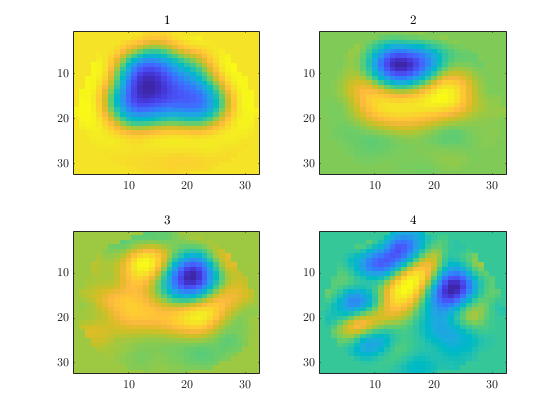

Ur = reshape(Ur, 32,32,[]);
figure; 
subplot(2,2,1);
imagesc(Ur(:,:,1)); title('1');
subplot(2,2,2);
imagesc(Ur(:,:,2)); title('2');
subplot(2,2,3);
imagesc(Ur(:,:,3)); title('3');
subplot(2,2,4);
imagesc(Ur(:,:,4)); title('4');

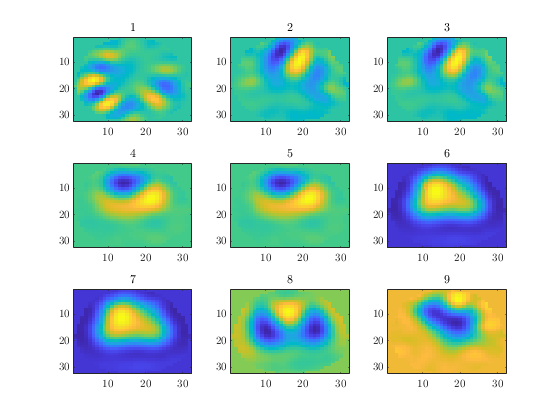

Phi2D = reshape(real(Phi), 32,32,[]);
figure;
subplot(3,3,1);
imagesc(Phi2D(:,:,1)); title('1');
subplot(3,3,2);
imagesc(Phi2D(:,:,2)); title('2');
subplot(3,3,3);
imagesc(Phi2D(:,:,3)); title('3');
subplot(3,3,4);
imagesc(Phi2D(:,:,4)); title('4');
subplot(3,3,5);
imagesc(Phi2D(:,:,5)); title('5');
subplot(3,3,6);
imagesc(Phi2D(:,:,6)); title('6');
subplot(3,3,7);
imagesc(Phi2D(:,:,7)); title('7');
subplot(3,3,8);
imagesc(Phi2D(:,:,8)); title('8');
subplot(3,3,9);
imagesc(Phi2D(:,:,9)); title('9');

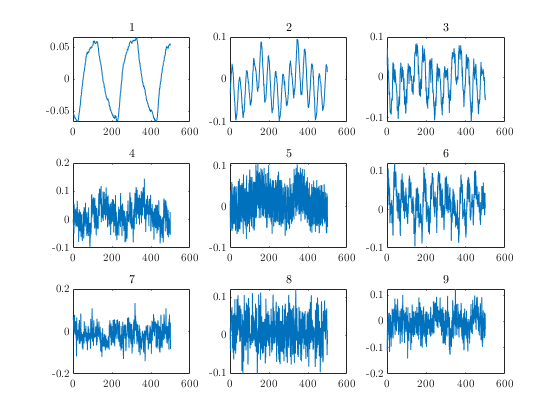

figure; 
figure;
subplot(3,3,1);
plot(Vr(:,1)); title('1');
subplot(3,3,2);
plot(Vr(:,2)); title('2');
subplot(3,3,3);
plot(Vr(:,3)); title('3');
subplot(3,3,4);
plot(Vr(:,4)); title('4');
subplot(3,3,5);
plot(Vr(:,5)); title('5');
subplot(3,3,6);
plot(Vr(:,6)); title('6');
subplot(3,3,7);
plot(Vr(:,7)); title('7');
subplot(3,3,8);
plot(Vr(:,8)); title('8');
subplot(3,3,9);
plot(Vr(:,9)); title('9');

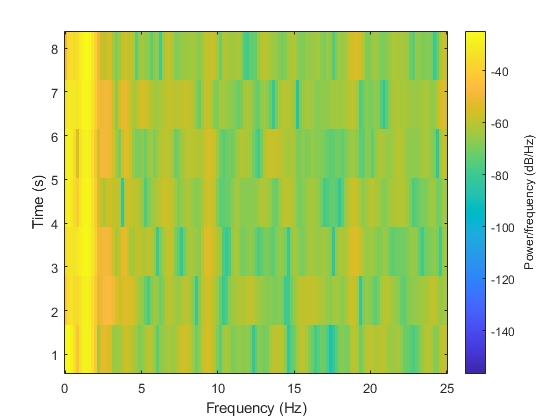

figure;spectrogram(Vr(:,2),[],[],[],50);

% Reconstructing the dynamics with linearized A
dt = 1/50;
lambda = diag(D);
omega = log(lambda)/dt;
x1 = X1(:,1);
b = Phi\x1;

mm1 = size(X1,2);
time_dynamics = zeros(r, mm1);
t = (0:mm1-1)*dt;
for iter = 1:mm1
    time_dynamics(:, iter) = (b.*exp(omega*t(iter)));
end
Xdmd = Phi * time_dynamics;

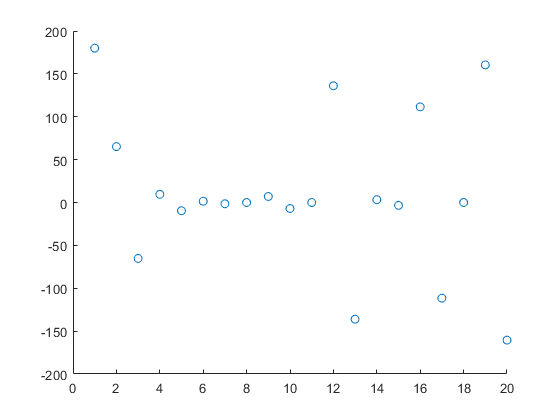

% Plot mode frequencies
figure; scatter(1:20,180*angle(lambda)/pi);

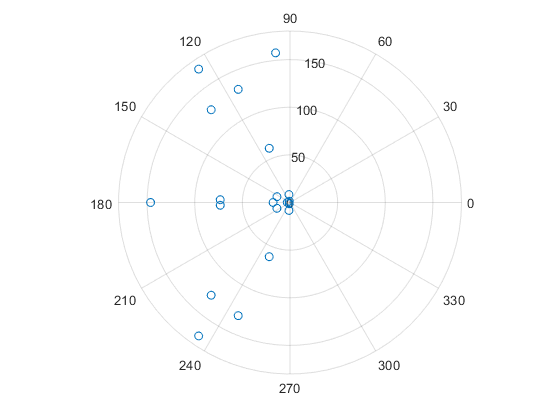

figure; polarplot(omega,'o')

% Filter through Phi
phiFilt = Phi;
% phiFilt(:,1:3) = 0;phiFilt(:,6:end) = 0;
% Xdmd = phiFilt * time_dynamics;

[~,I] = sort(abs(omega));
phiFilt = phiFilt(:,I);
time_dynamics = time_dynamics(I,:);
phiFilt(:,1:2) = 0; phiFilt(:,10:end) = 0;
Xdmd = phiFilt * time_dynamics;

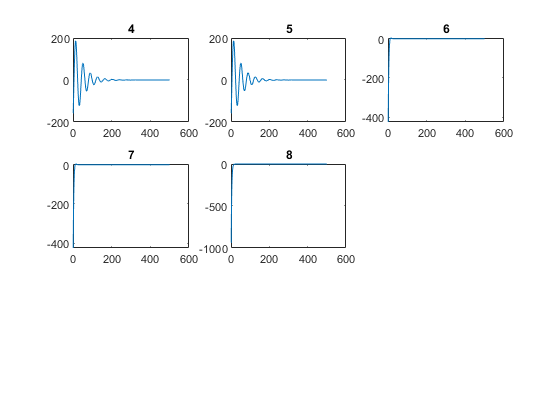

figure; 
subplot(3,3,1);
plot(real(time_dynamics(4,:))); title('4');
subplot(3,3,2);
plot(real(time_dynamics(5,:))); title('5');
subplot(3,3,3);
plot(real(time_dynamics(6,:))); title('6');
subplot(3,3,4);
plot(real(time_dynamics(7,:))); title('7');
subplot(3,3,5);
plot(real(time_dynamics(8,:))); title('8');

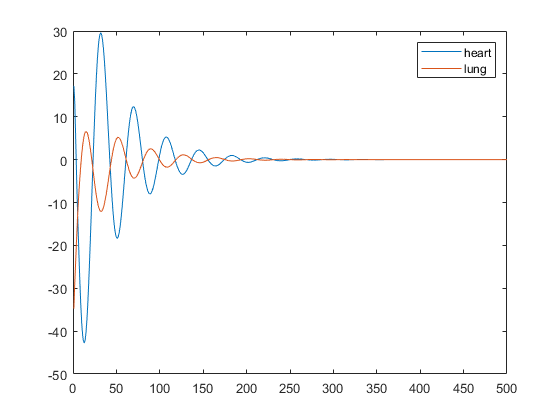

Xdmd2D = real(reshape(Xdmd, 32,32,[]));

heartPix = [7,15];
lungPix = [17,10];

figure;
plot(squeeze(Xdmd2D(heartPix(1),heartPix(2),:))); hold on; plot(squeeze(Xdmd2D(lungPix(1),lungPix(2),:))); legend({'heart','lung'}); 

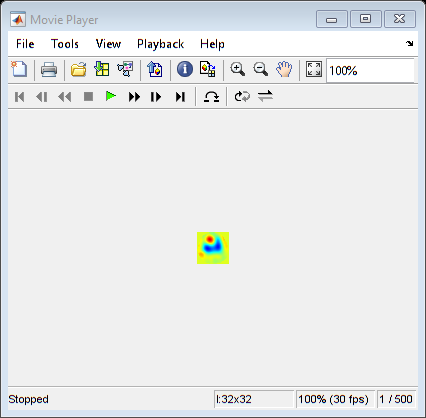

h =   UnifiedScope with properties:

    InstanceNumber: 1
     Specification: [1×1 iptscopes.IMPlayScopeCfg]
        MessageLog: []
            Visual: [1×1 iptscopes.VideoVisual]
        DataSource: [1×1 matlabshared.scopes.source.WorkspaceSource]
            Parent: [1×1 Figure]


h = playVideo(Xdmd2D)

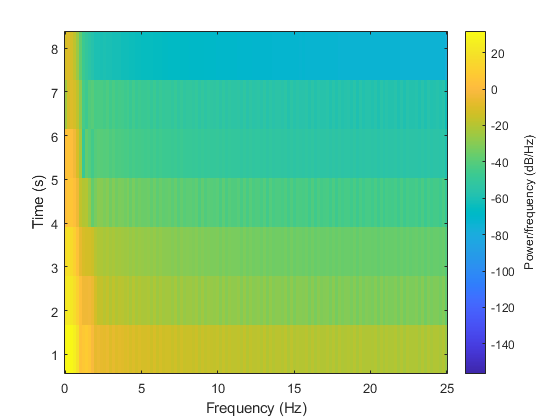

figure;spectrogram(squeeze(Xdmd2D(lungPix(1),lungPix(2),:)),[],[],[],50);